% E9.1
clear all
s = tf('s');

Ls = 3*(1+5*s)/(s*(4+s)*(1+2*s+2*s^2))

Ls =
 
            15 s + 3
  ----------------------------
  2 s^4 + 10 s^3 + 9 s^2 + 4 s
 
연속시간 전달 함수입니다.
모델 속성


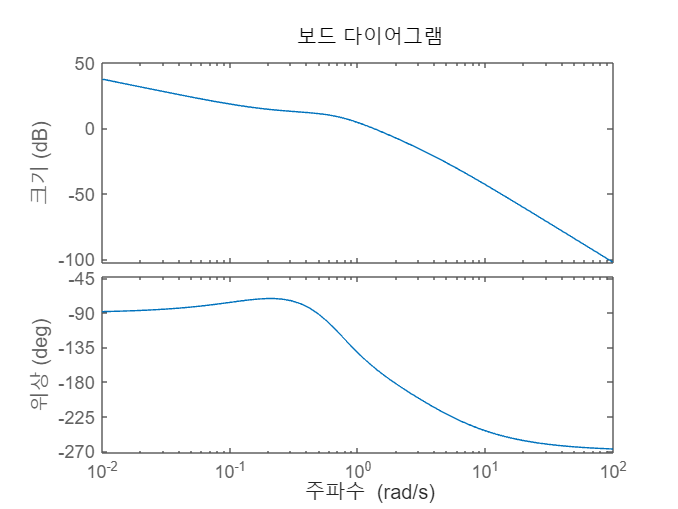

sys = Ls;
bode(sys);

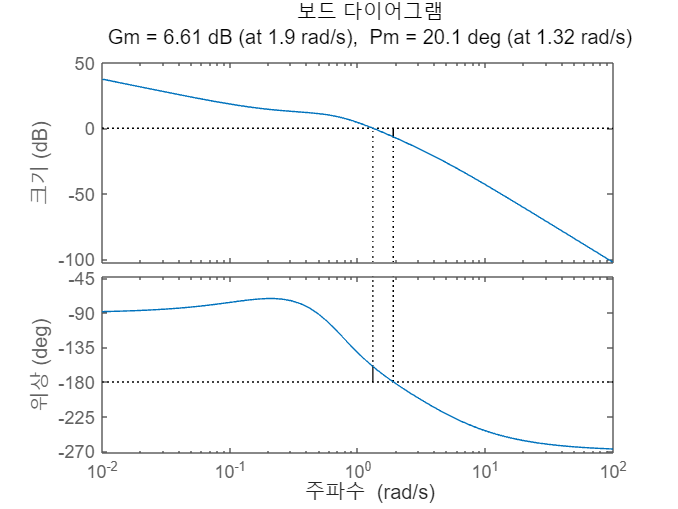

margin(sys);

[Gm, Pm] = margin(sys);
Gm = mag2db(Gm);
Pm;
fprintf("G.M. = %.2f[dB]\nP.M. = %.1f[°]", [Gm, Pm])

G.M. = 6.61[dB]
P.M. = 20.1[°]